# Thevenin and Norton Equivalent Circuits

[⇦ DC Circuit Analysis Overview](matlab: OpenOverview)

**Learning Goals**

- Explain Thevenin and Norton equivalent circuits.

- Solve for Thevenin and Norton equivalents.

- Compare circuits to their Thevenin and Norton equivalents.

## Introduction

You are probably already familiar with the idea that series and parallel resistors can be represented by simpler equivalent resistances.

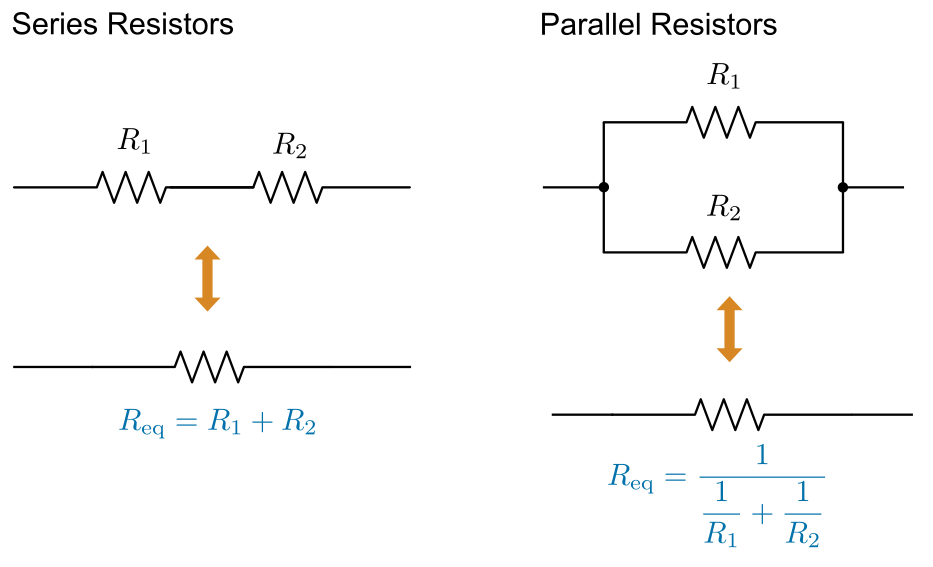

*Resistor equivalents*

*Thevenin* and *Norton equivalent circuits *are similar in that they allow multiple elements to be reduced into fewer equivalent elements. In particular, they allow complex linear circuits with resistors, current sources, and voltage sources to be reduced into just two equivalent circuit elements: an equivalent resistance and an equivalent source.

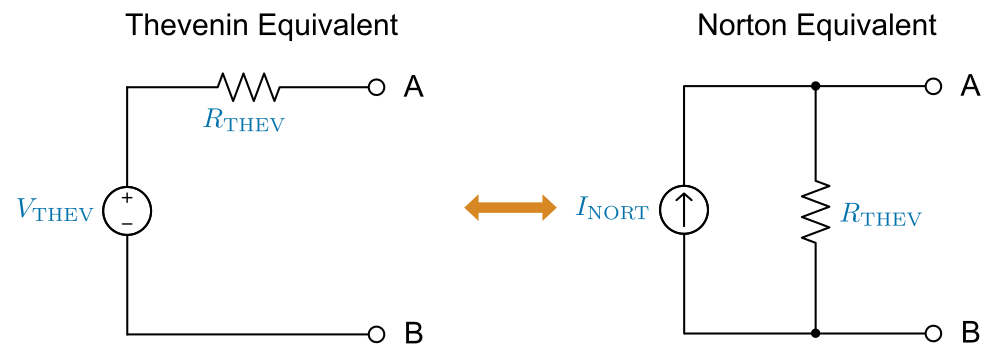

*Thevenin and Norton equivalent circuits. The Thevenin circuit contains a voltage source, while the Norton circuit contains a current source.*

## Thevenin equivalent circuits

A Thevenin equivalent simplifies a linear circuit down to a single equivalent resistance, $R_{\text{THEV}}$, and equivalent voltage source, $V_{\text{THEV}}$.

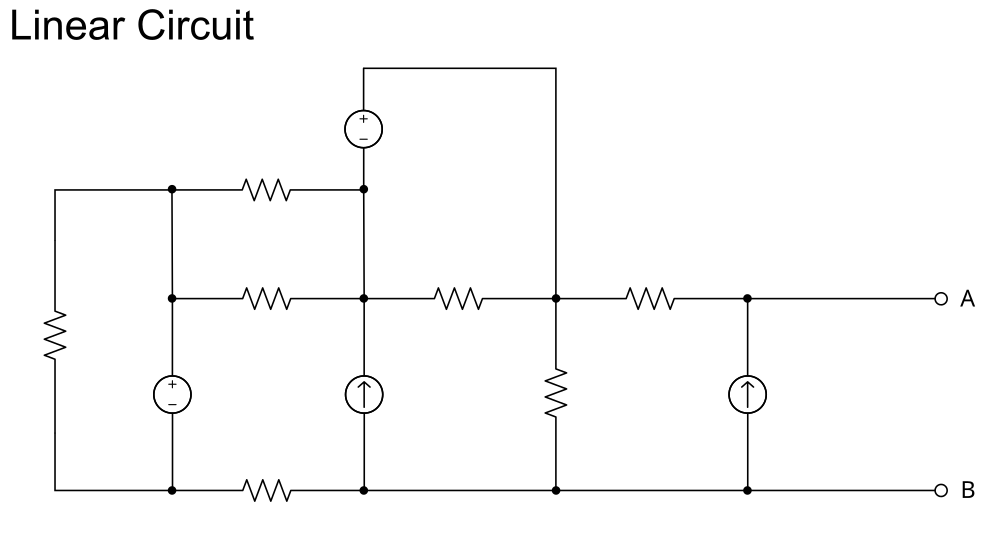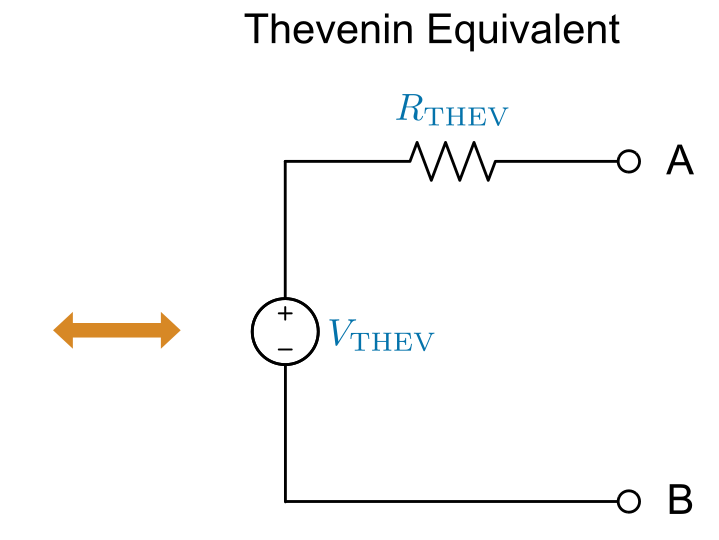

*This linear circuit can be represented by its Thevenin equivalent with respect to terminals A and B.*

A Thevenin equivalent is created with respect to any two terminals in a circuit. Relative to those terminals, the behavior of the Thevenin circuit will be identical to the full circuit (assuming that the original circuit has only resistors, voltage sources, and current sources). To model the behavior relative to two other points in the circuit, you must construct a new Thevenin equivalent. If a load resistor exists at the location of interest, disconnect it to create an open circuit and replace it after computing the Thevenin equivalent.

  **Activity. **In this activity, you will compare a simulated linear circuit to its Thevenin equivalent. Open the model:

[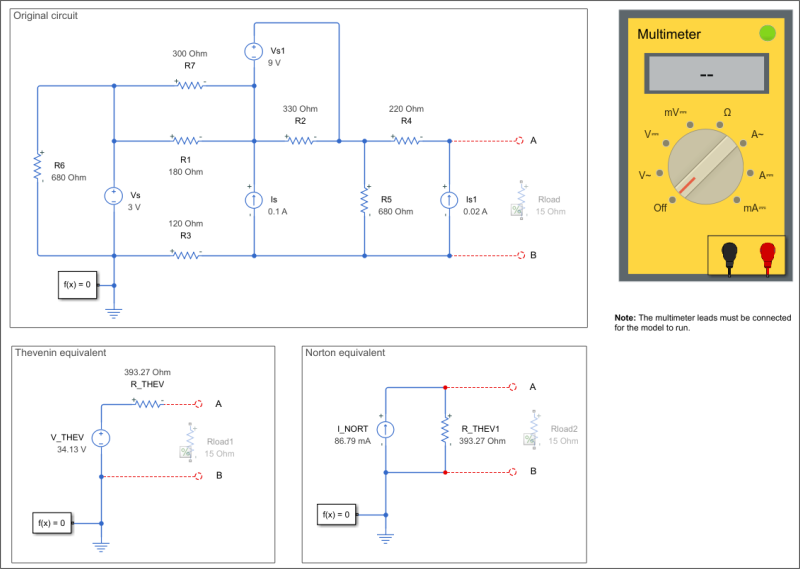](matlab: EquivalentCircuitDemo)

[`EquivalentCircuitDemo.slx`](matlab: EquivalentCircuitDemo)

**Note: **Watch [this 2-minute instructional video](https://user-images.githubusercontent.com/81383420/145589989-f7ae4a32-cab3-405d-b7e8-476e34d697b5.mp4) to learn how to use the virtual multimeter.

- Measure the voltage between A(+) and B(-) in the original circuit. This is the Thevenin voltage, $V_{\text{THEV}}$. Then, measure the voltage between A(+) and B(-) in the Thevenin equivalent circuit. Do the voltages match? Note that there may be minor round-off errors.

- Uncomment the load resistor (right-click the resistor and select **Uncomment**) and attach it to the circuit between A and B in both the original and Thevenin circuits. 

- Measure the current through the load resistor in both circuits by connecting the multimeter in series with the load resistor. What is the current in each case? Are they equal?

- Change both load resistors to 100 $\Omega$ and measure the currents in each case again. Are they equal?

**Calculating the Thevenin equivalent**

You can compute the Thevenin equivalent using three steps.

- If a load resistor exists between the nodes of interest, disconnect it to open the circuit.

- Compute the equivalent resistance, $R_{\text{THEV}}$. The Thevenin resistance is the circuit's equivalent resistance if all the voltage sources are shorted, and the current sources are replaced with open circuits. See the diagram below for reference.

- Compute the equivalent voltage, $V_{\text{THEV}}$. This is the open-circuit voltage between the desired nodes in the original circuit.

**Note**: do not use the Thevenin resistance while computing $V_{\text{THEV}}$. You must derive $V_{\text{THEV}}$ from the original circuit.

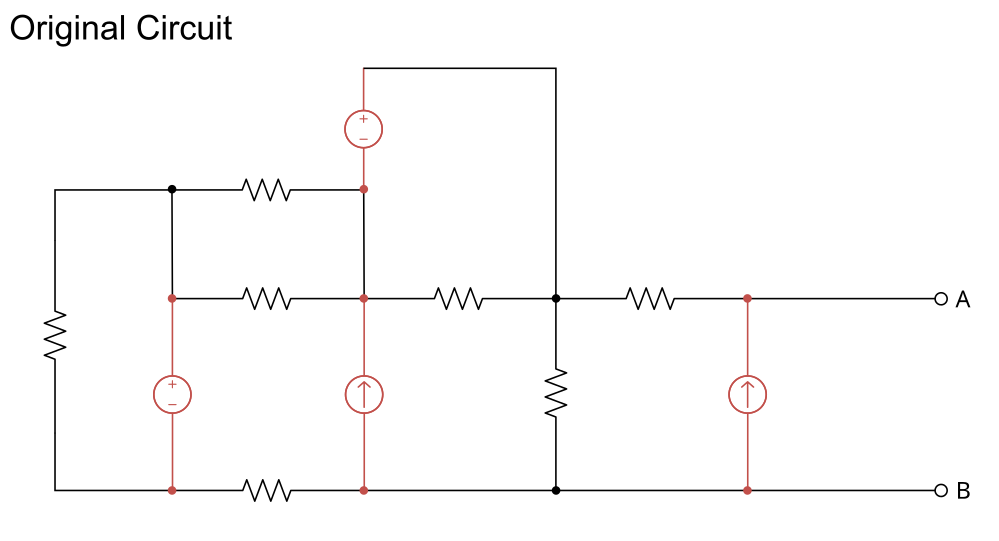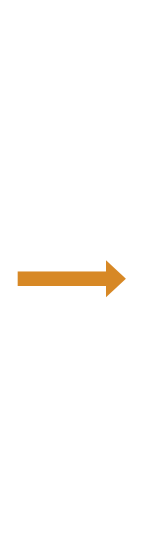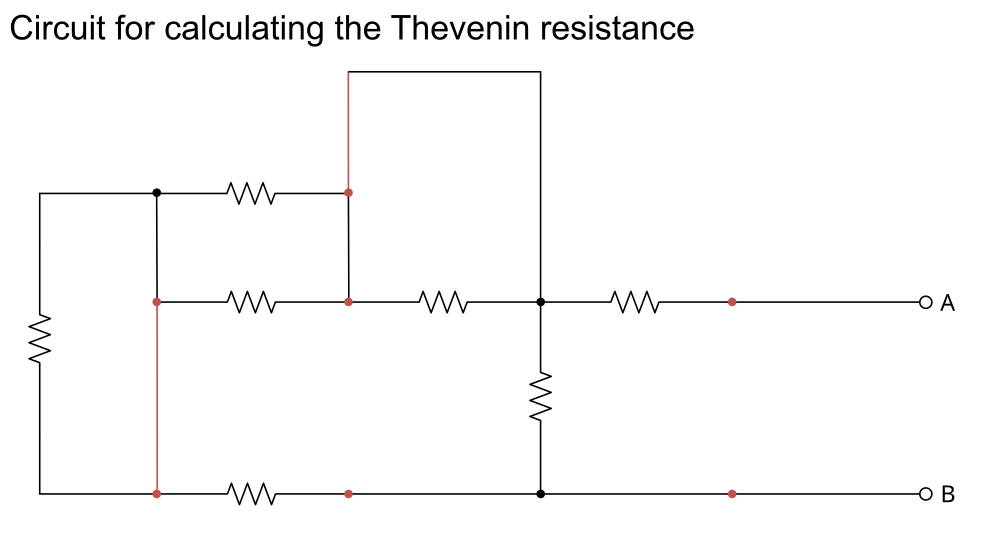

*Example of a circuit used to calculate the Thevenin equivalent resistance. The voltage sources are shorted (replaced with a wire), and the current sources are removed.*

 **Example. ** Compute the Thevenin equivalent of the linear circuit relative to $A$ and $B$.

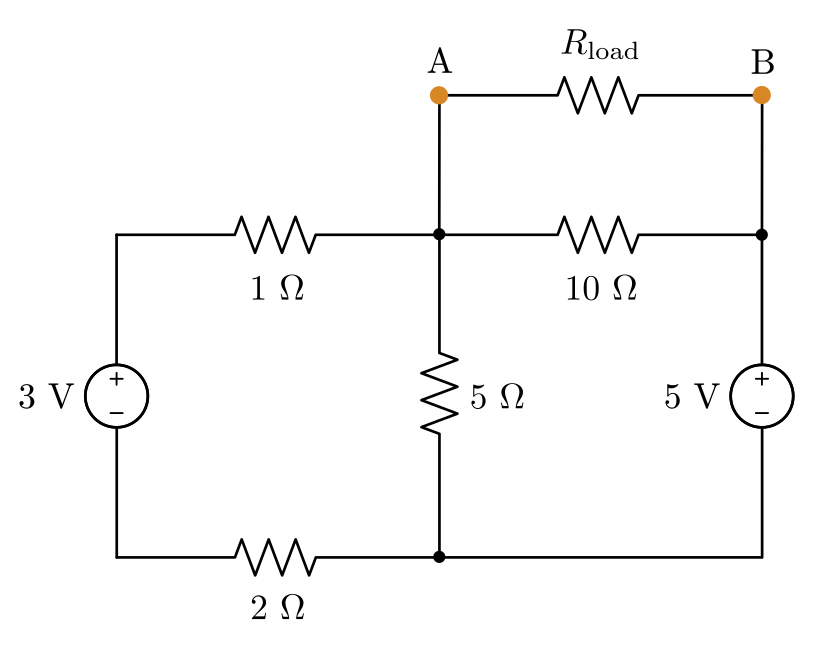

**Step 1. **Start by disconnecting the load resistor to create a short circuit between $A$ and $B$. 

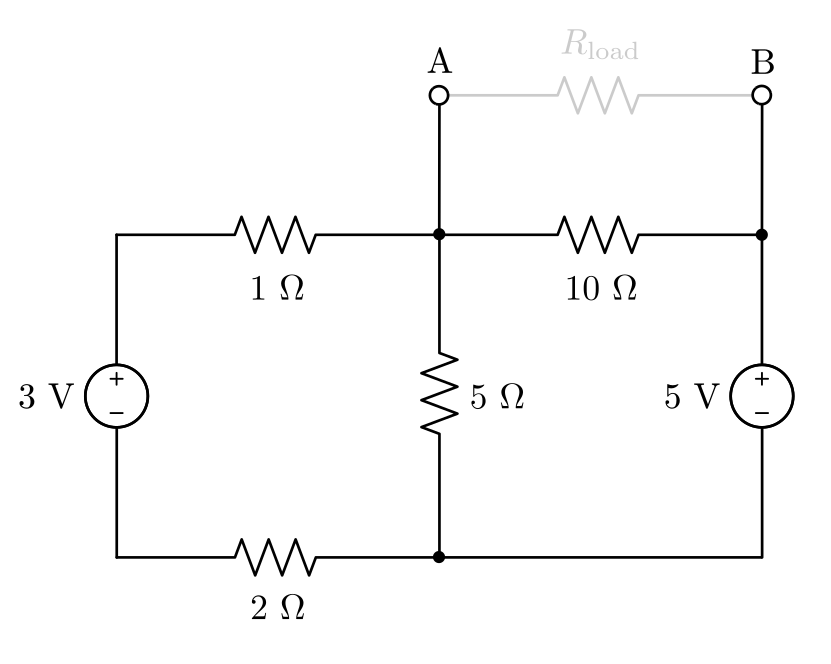

**Step 2. **Compute the Thevenin equivalent resistance by short-circuiting the voltage sources and then reducing the circuit to a single resistor.

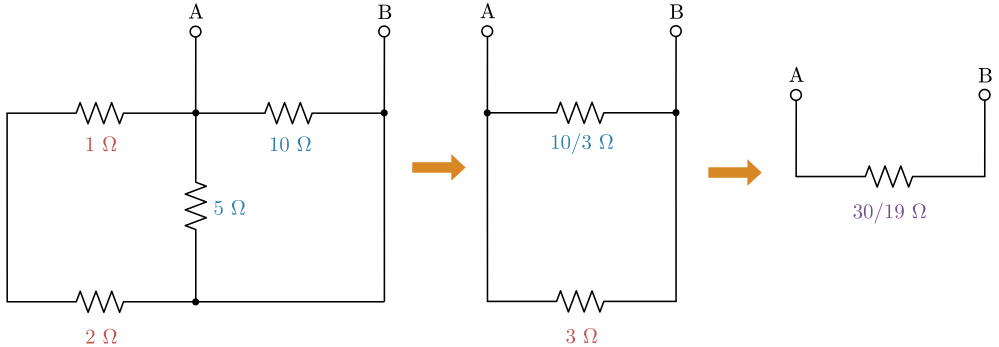

The Thevenin resistance is therefore $R_{\text{THEV}} = 30/19 \ \Omega \approx 1.58 \ \Omega$.

**Step 3. **The Thevenin voltage is the open-circuit voltage between $A$ and $B$ in the original circuit. This can be computed using nodal analysis. Suppose that the reference node is as shown. 

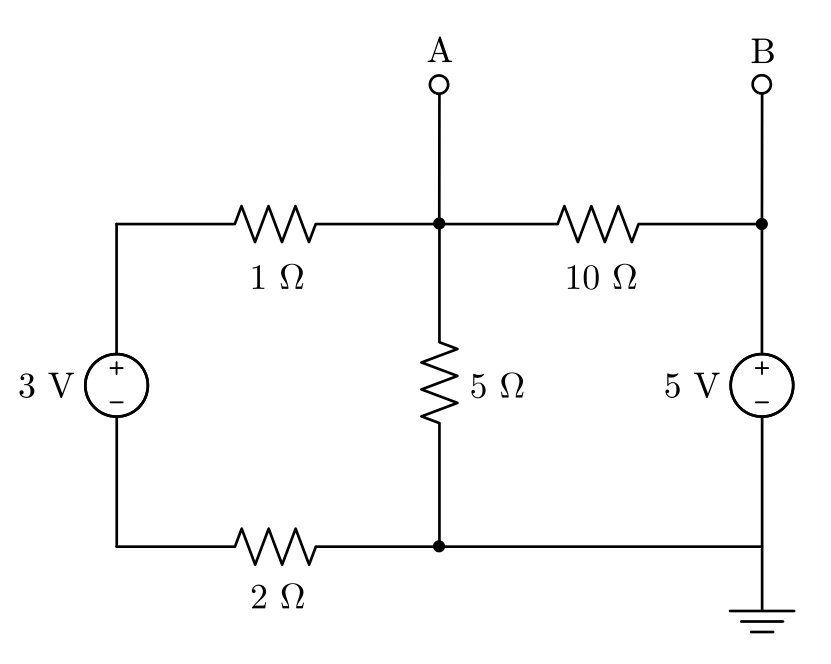

The voltage at node $B$ is $V_B = 5 $ V and so only one equation is necessary for the voltage at node $A$:


$$\frac{0 + 3 - V_A}{3} + \frac{0-V_A}{5} + \frac{5-V_A}{10} = 0$$


Solve and find that $V_A = 45/19 $ V.  Therefore the open-circuit voltage between $A$ and $B$ is $V_{\text{THEV}} =   -50/19 \approx -2.63$ V. The overall equivalent circuit is shown below.

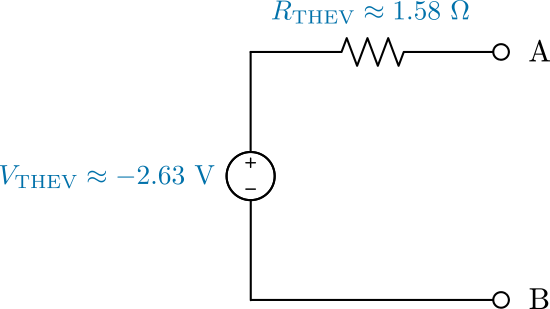

## Norton equivalent circuits

A Norton equivalent simplifies a linear circuit down to a single equivalent resistance, $R_{\text{THEV}}$, and equivalent current source, $I_{\text{NORT}}$. 

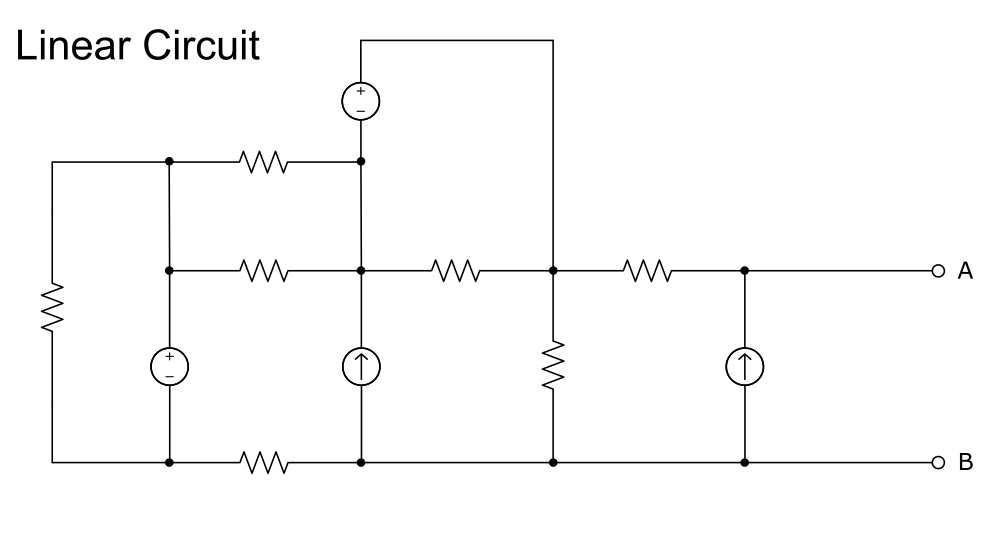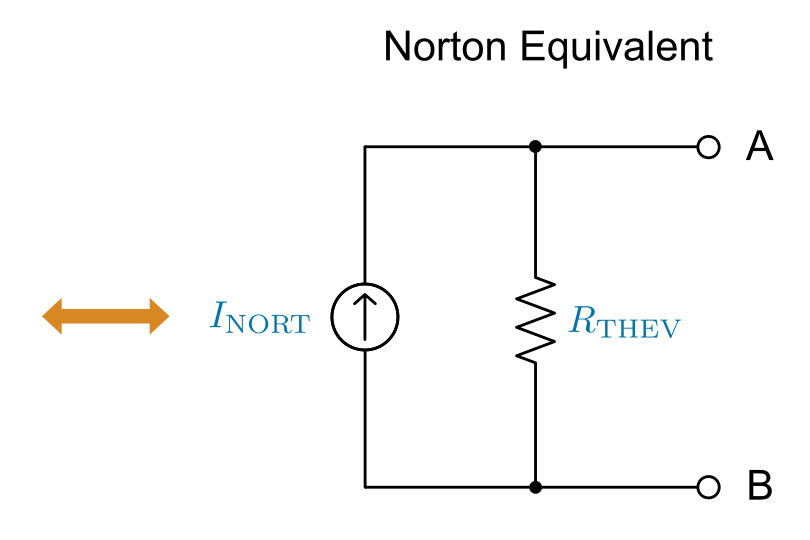

*This linear circuit can be represented by its Norton equivalent with respect to terminals A and B.*

Like the Thevenin equivalent circuit, the Norton equivalent is constructed with respect to two terminals in the circuit. Did you notice that the Norton equivalent resistance is labeled $R_{\text{THEV}}$ instead of $R_{\text{NORT}}$? That's not a typo – the Norton equivalent resistance is the same as the Thevenin equivalent resistance. 

In addition, Thevenin and Norton circuits are interchangeable. If you have already solved for the Thevenin voltage, you can solve for the Norton current $I_{\text{NORT}}$ as the short circuit current through the terminals of the Thevenin equivalent. Similarly, if you have already solved for the Norton equivalent, you can solve for $V_{\text{THEV}}$ as the open-circuit voltage between the terminals of the Norton circuit.

*You can convert between Thevenin and Norton equivalents using a simple calculation.*

The Norton equivalent current is computed from the Thevenin equivalent circuit as


$$I_{\text{NORT}} = \frac{V_{\text{THEV}}}{R_{\text{THEV}}}$$


Multiplying by $R_{\text{THEV}}$ will provide the formula for the Thevenin voltage from the Norton current.

  **Activity. **In this activity, you will compare a simulated linear circuit to its Norton equivalent. Open the model:

[](matlab: EquivalentCircuitDemo)

[`EquivalentCircuitDemo.slx`](matlab: EquivalentCircuitDemo)

- If any load resistors are connected, remove them. Also disconnect the multimeter leads.

- Measure the short-circuit current between A(+) and B(-) in the original circuit. This is the Norton current, $I_{\text{NORT}}$. Then, measure the short-circuit current in the Norton equivalent. Do the results match? Note that there may be minor round-off errors.

- Measure the short-circuit current between the Thevenin equivalent terminals. Does it match the current through the Norton equivalent and original circuit terminals? 

- Uncomment the load resistor (right-click the resistor and select **Uncomment**) and attach it to the circuit between A and B in both the original and Norton circuits. 

- Measure the current through the load resistor in each circuit by connecting the multimeter in series with the load resistor. What is the current in each case? Are they equal?

**Calculating the Norton equivalent**

You can compute the Norton equivalent using three steps.

- If a load resistor exists between the nodes of interest, disconnect it.

- Compute the equivalent resistance, $R_{\text{THEV}}$. The Thevenin resistance is the equivalent resistance of the circuit if all the voltage sources are shorted and open circuits have replaced the current sources.

- Short circuit the terminals in the original circuit and compute the short circuit current. The short circuit current through the terminals is $I_{\text{NORT}}$.

 **Example. ** Compute the Norton equivalent of the linear circuit with respect to $A$ and $B$.

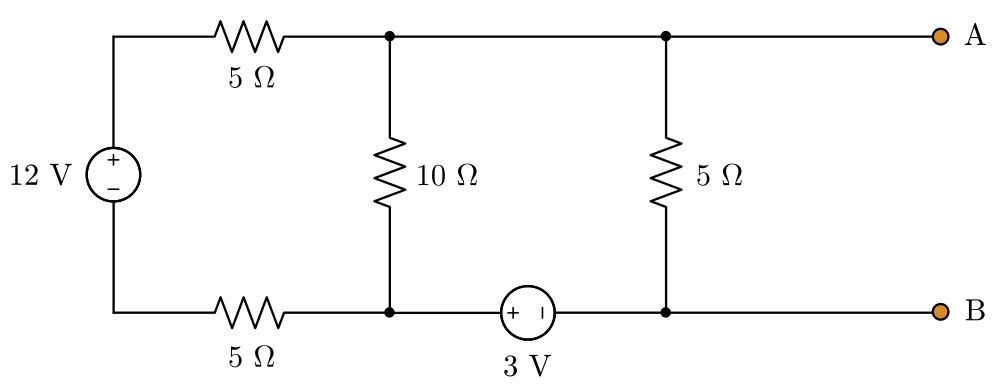

**Step 1. **No load resistor exists, so this step is not required.

**Step 2. **Short the voltage sources and solve for $R_{\text{THEV}}$.

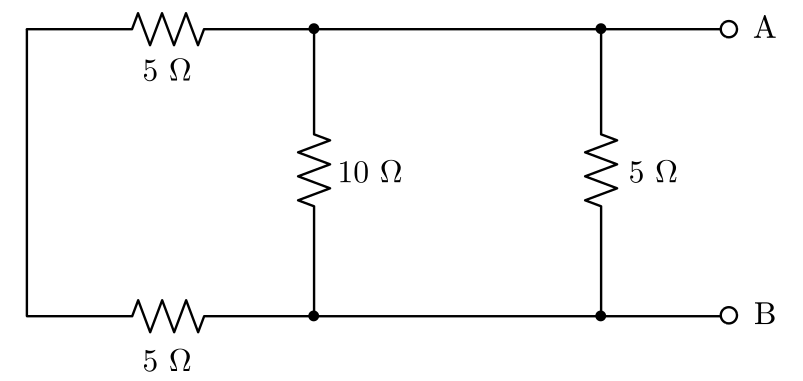

Combining the resistors implies an equivalent resistance $R_{\text{THEV}} = 2.5 \ \Omega$.

**Step 3. **You can use mesh analysis (described in [MeshAnalysis.mlx](matlab: edit MeshAnalysis.mlx)) to compute the short-circuit current between $A$ and $B$ in the original circuit. Shorting $A$ and $B$ produces the following diagram:

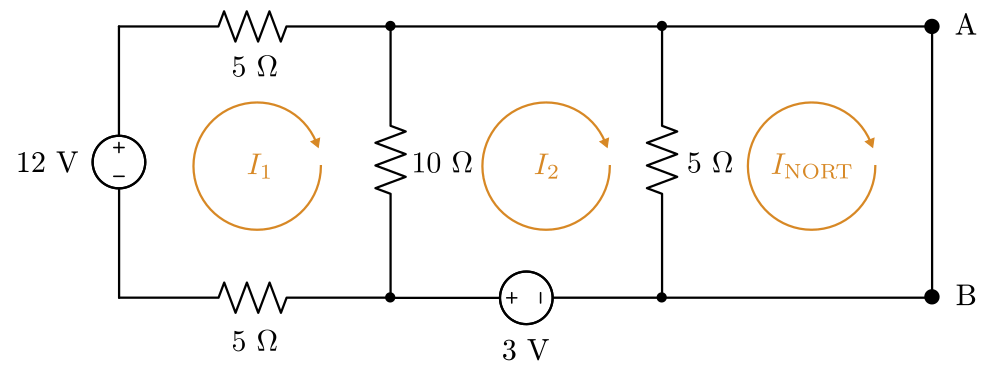

Notice that the final mesh current is the desired short-circuit current between $A$ and $B$, $I_{\text{NORT}}$. Applying KVL yields the mesh equations:


$$\begin{array}{rr}
-12  + 5I_1 + 10(I_1 - I_2) + 5 I_1 &= 0
\\
10 (I_2 - I_1) + 5(I_2 - I_{\text{NORT}}) - 3 &= 0
\\ 
5(I_{\text{NORT}} - I_2) &= 0
\end{array}$$


The mesh currents can be computed by setting up the matrix equation in MATLAB.

% Solve for the currents
A = [20, -10,  0 
     -10,  15, -5
      0   -5,  5];
b = [12; 3; 0];
I = A\b
Inort = I(3) % The third mesh current is the Norton equivalent current

Implying the final Norton equivalent:

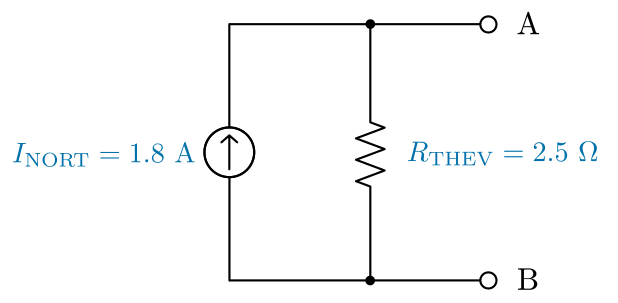

[⇦ DC Circuit Analysis Overview](matlab: OpenOverview)